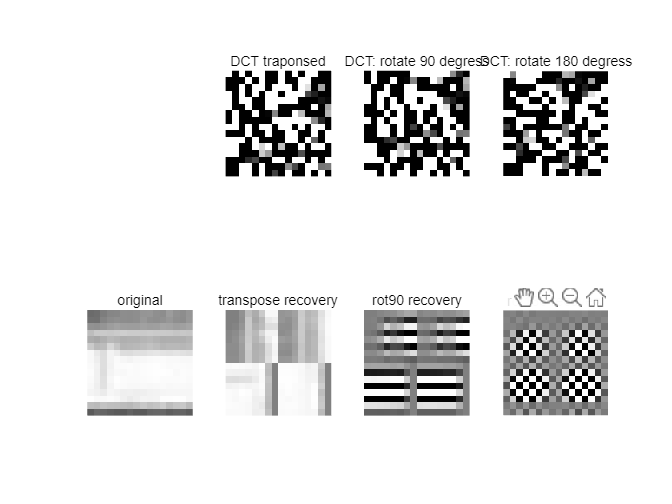

%Ch2_3.mlx
%block processing recovery; zero left/right
load JpegCoeff.mat;
load hall.mat;
raw=hall_gray(56:71,56:71);
%reference:https://www.mathworks.com/help/images/distinct-block-processing.html

%transpose, rotate 90 degrees and 180 degrees
dct_t=@(block_struct) dct_transpose(block_struct.data);
dct_r_90=@(block_struct) dct_rot_90(block_struct.data);
dct_r_180=@(block_struct) dct_rot_180(block_struct.data);
%inverse transform
idct_n=@(block_struct) idct_normal(block_struct.data);
%coefficient matrices
T=blockproc(raw,[8,8],dct_t);
R_90=blockproc(raw,[8,8],dct_r_90);
R_180=blockproc(raw,[8,8],dct_r_180);
%recovered matrices
R=blockproc(T,[8,8],idct_n);
R_l=blockproc(R_90,[8,8],idct_n);
R_r=blockproc(R_180,[8,8],idct_n);

%start to plot...
figure;
subplot(2,4,5);
imshow(raw);
title("original");

subplot(2,4,2);
imshow(T);
title("DCT traponsed");

subplot(2,4,3);
imshow(R_90);
title("DCT: rotate 90 degress");

subplot(2,4,4);
imshow(R_180);
title("DCT: rotate 180 degress");

subplot(2,4,6);
imshow(R);
title("transpose recovery");

subplot(2,4,7);
imshow(R_l);
title("rot90 recovery");

subplot(2,4,8);
imshow(R_r);
title("rot180 recovery");

function C=dct_transpose(P)
C=dct2(double(P-128));
C=C';
end

function C=dct_rot_90(P)
C=dct2(double(P-128));
C=rot90(C);
end

function C=dct_rot_180(P)
C=dct2(double(P-128));
C=rot90(rot90(C));
end

function P=idct_normal(C)
P=uint8(idct2(C)+128);
end